% Curva de calibración
c=10:10:100; % concentraciones
n=[1.343 1.344 1.35 1.3560 1.3580 1.3610 1.3650 1.3660 1.3670 1.3680]; % indice de refracción
aj=polyfit(c,n,1); % Ajuste
%ecuación de la recta
m=aj(1)

m = 3.0061e-04

b=aj(2)

b = 1.3413


% gráfica 
plot(c,n,'k.',[0 100],[polyval(aj,0),polyval(aj,100)])
grid on
grid minor
hold on 

% Bebidas comerciales
 nb=[1.3573 1.3472 1.34]; % indice de refracción
 xb=(nb-aj(2))./aj(1) % cálculo de concentración

xb =    53.3367   19.7379   -4.2137


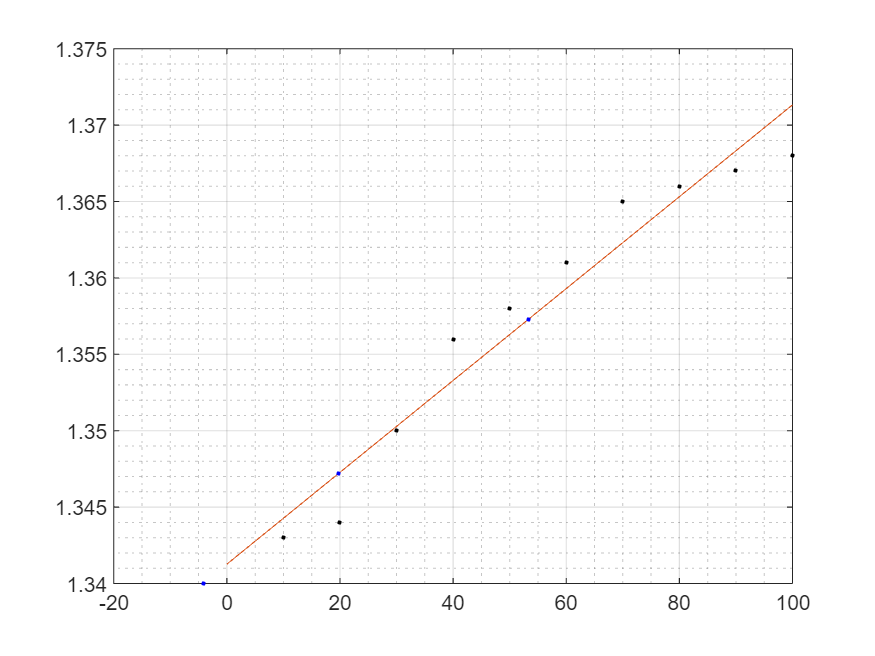

 plot(xb,nb,'b.','LineWidth',2)
 hold off

clc; clear all;
format long
 x = [2 6 10 14 18];
y = [0.065 0.205 0.338 0.474 0.598];
p = polyfit(x,y,1);
f = polyval(p,x);
m=p(1)

m =    0.033375000000000


b=p(2)

b =    0.002250000000000


[r2 rmse] = rsquare(y,f);
plot(x,y,'b*');
hold on; 
plot(x,f,'k-','LineWidth',1);
xlim([0 x(end)+1])
grid on
grid minor
title(strcat(['$R^2$ = ' num2str(r2) '\qquad\qquad\qquad\qquad RMSE = ' num2str(rmse)]), 'interpreter', 'latex'); 
xlabel('Concentracion ($\mu$M)', 'interpreter', 'latex')
ylabel('Absorbancia (550 nm)', 'interpreter', 'latex')
% Datos experimentales
 nb=[0.402]; % datos obtenidos
 xb=(nb-p(2))./p(1) % cálculo de y

xb =   11.977528089887638


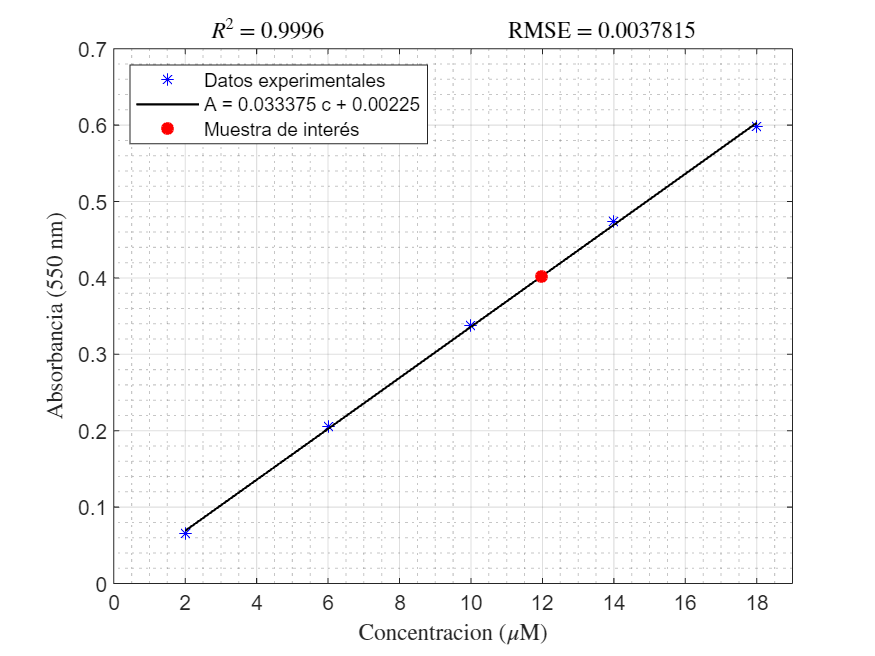

 plot(xb,nb,'r*','LineWidth',2)
 legend("Datos experimentales",['A = ' num2str(m) ' c + ' num2str(b)],"Muestra de interés",'Location','northwest')
 hold off